clear all

### Problema 1

Adelanto de fase

Diseñe un compensador de adelanto de fase 𝐺𝐺𝐶𝐶 (𝑠𝑠) tal que, en lazo cerrado, el margen de fase sea

𝑃𝑀 ≈ 45° y el margen de ganancia sea 𝐺𝑀 > 8𝑑b. Considere una constante estática de error de

velocidad de 𝑐𝑣 = 4𝑠eg−1.

syms s Kc
syms w
G_s = 32/(s*(0.1*s + 1)*(s + 1))

$$G\_s = \frac{32}{s\,\left(\frac{s}{10}+1\right)\,\left(s+1\right)}$$

Pmd = 45;
Gmd = 8;
Cv = 4

Cv = 4

Paso 1: Obtener la ganancia Kc

Kc_val = solve(Cv == limit(s*G_s*Kc, s, 0), Kc)

$$Kc\_val = \frac{1}{8}$$

Kc_val = double(Kc_val);

Paso 2: Obtener Pm de G(s)*Kc

[Gm, Pm] = margin(sym2tf(G_s)*Kc_val)

Gm = 2.7500

Pm = 17.7051

Paso 3: Obtener la fase 

compTest = 14.4 % 5 - 12 grados

compTest = 14.4000


phim = deg2rad(Pmd-Pm+compTest)

phim = 0.7277

Paso 4: Obtener beta con phim

beta=(1-sin(phim))/(1+sin(phim))

beta = 0.2011

Paso 5: Obtener la frecuencia omega que cumpla con lo siguiente:

|G(wi)|^2 = beta

*Tenemos que sustituir s por wi y despejar w

L_s = Kc_val*G_s

$$L\_s = \frac{4}{s\,\left(\frac{s}{10}+1\right)\,\left(s+1\right)}$$

L_jw = subs(L_s, s, 1i*w)

$$L\_jw = -\frac{4\,\mathrm{i}}{w\,\left(1+w\,\mathrm{i}\right)\,\left(1+\frac{w\,\mathrm{i}}{10}\right)}$$

w_val = vpasolve(abs(L_jw)^2 == beta, w, [0 100])

$$w\_val = 2.8450385956512045205925051055919$$

w_val = double(w_val)

w_val = 2.8450

Paso 6: 

Calcular beta1 y beta2

beta1=sqrt(beta)*w_val

beta1 = 1.2758

beta2=w_val/sqrt(beta)

beta2 = 6.3446

Paso 7: Comprobar si se obtuvieron los requerimientos deseados calculando Gm y Pm de Gc(s)*G(s)

Gc=(Kc_val/beta)*tf([1 beta1],[1 beta2])

Gc =
 
  0.6216 s + 0.7931
  -----------------
      s + 6.345
 
Continuous-time transfer function.
Model Properties


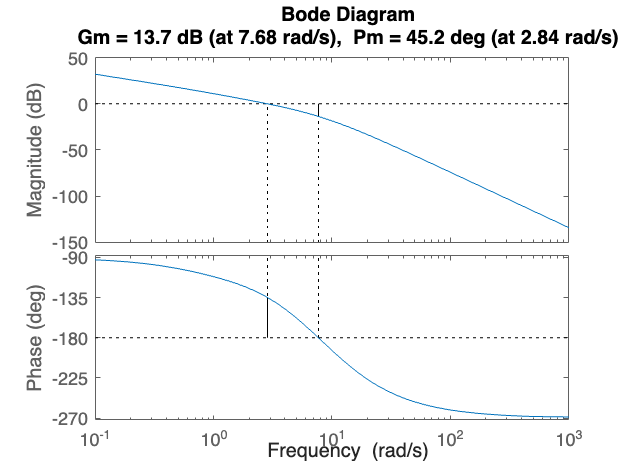

margin(Gc*sym2tf(G_s))

**Problema 2**

Atraso     de fase

syms s Kc
syms w
G_s = (2*s+0.1)/(s^2+0.1*s+4)

$$G\_s = \frac{2\,s+\frac{1}{10}}{s^{2}+\frac{s}{10}+4}$$

Pmd = 45;
Gm = 8;
Cv = 4

Cv = 4

Paso 1: Obtener la ganancia Kc

Kc_val = solve(Cv == limit(s*G_s*Kc, s, 0), Kc)

 
Kc_val =
 
Empty sym: 0-by-1
 


Kc_val = double(Kc_val);

Paso 2: Obtener Pm de G(s)*Kc

[Gm, Pm] = margin(sym2tf(G_s)*Kc_val)

Error using DynamicSystem/margin (line 55)
MARGIN requires a SISO model.

Paso 3: Obtener la fase 

compTest = 6 % 5 - 12 grados

phim = deg2rad(Pmd-Pm+compTest)

Paso 4: Obtener beta con phim

beta=(1-sin(phim))/(1+sin(phim))

Paso 5: Obtener la frecuencia omega que cumpla con lo siguiente:

|G(wi)|^2 = beta

*Tenemos que sustituir s por wi y despejar w

L_s = Kc_val*G_s
L_jw = subs(L_s, s, 1i*w)
w_val = vpasolve(abs(L_jw)^2 == beta, w, [0 20])
w_val = double(w_val)
% Convertimos a decibelios
omeg=20*log10(w_val);

Paso 6: 

Calcular beta1 y beta2

beta1=sqrt(beta)*omeg
beta2=omeg/sqrt(beta)

Paso 7: Comprobar si se obtuvieron los requerimientos deseados calculando Gm y Pm de Gc(s)*G(s)

Gc=(Kc_val/beta)*tf([1 beta1],[1 beta2])
margin(Gc*sym2tf(G_s))